This is a dataset from a "Two back" working memory experiment. The dataset contains reaction times (rt_data 249x24x2) from 249 trials of 24 subjects during two conditions as well as the average accuracy (acc_data 24x2). Conditions were positive and negative words. 

***File: Behavioral_Data.mat***

**1. Compare histograms of reaction times (RT) across two conditions from one subject. Example as below, you can choose randomly some subjects to show.**

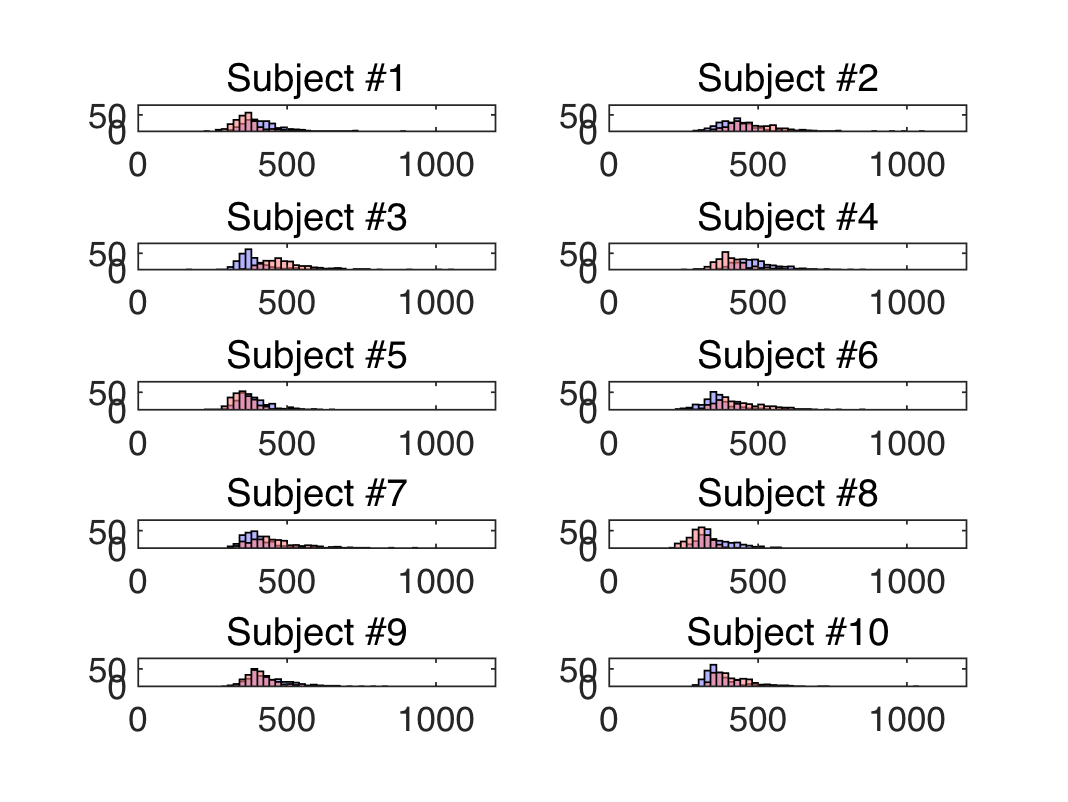

clc,clear all
load Behavioral_Data.mat; % load data
% for subject #1~#10, compare the histograms of RT across two conditions, do these in a loop 
xbin=0:20:1200; % define bin length for x-axis
figure
for i=1:10 ,subplot(5,2,i)
histogram(rt_data(:,i,1),xbin,'FaceColor',[.5 .5 1]);
hold on
histogram(rt_data(:,i,2),xbin,'FaceColor',[1 .5 .5]);
title(['Subject #' num2str(i)]);
xlim([0 1200]); %% define the region of X axis
ylim([0 80]); %% define the region of Y axis
end

**2. Test if the RT distribution is normal using the Kolmogorov-Smimov test. Plot histogram and distribution fit as below, using normal and a logistic distribution. **

% 正态性检验
A=reshape(rt_data,1,249*24*2); 
[H1,s1] = kstest(A);
if H1 == 0 disp('RT服从正态分布。');
else disp('RT不服从正态分布。');
end

RT不服从正态分布。


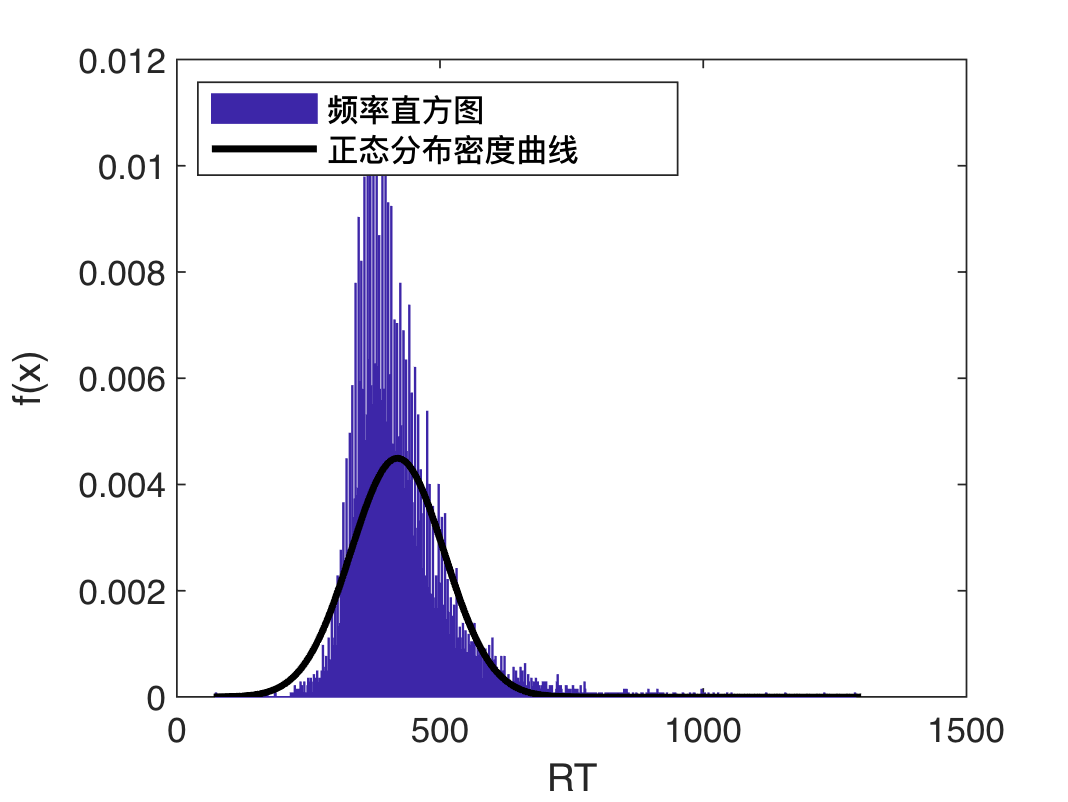


%% 频数(率)直方图 
figure;
[f, xc] = ecdf(A); ecdfhist(f, xc, 1000); 
xlabel('RT'); ylabel('f(x)');
x = 70:1300;
y = normpdf(x,mean(A),std(A));
hold on
plot(x,y,'k','LineWidth',2); 
legend('频率直方图','正态分布密度曲线','Location','NorthWest');

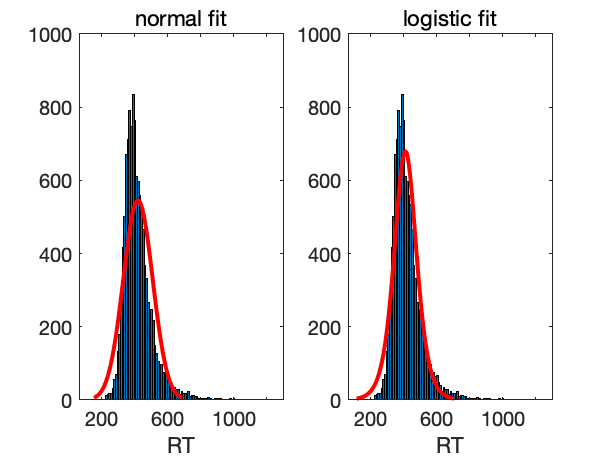


% 正态拟合作图 
figure;
subplot(1,2,1); histfit(A,120,'normal'); 
title('normal fit' ); xlabel('RT');
%logistic regression 
subplot(1,2,2); histfit(A,120,'logistic'); 
title('logistic fit' ); xlabel('RT');

**3. Bar graph of comparing mean reaction times across conditions. Run a t-test to see whether there is a significant difference in RT across conditions, if RT is normally distributed. If not, what test should we use? **

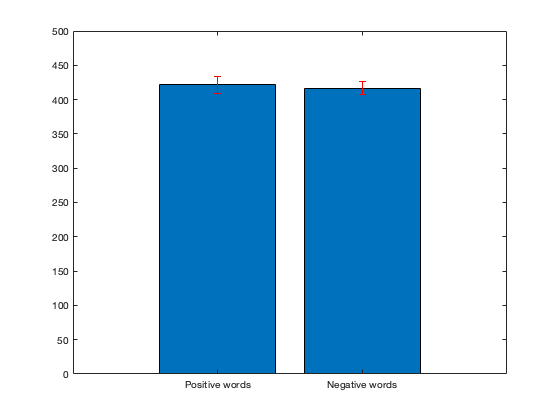

%% Bar graph of comparing mean reaction times across conditions
mean_rt = squeeze(mean(mean(rt_data)));
ste_rt = squeeze(std(mean(rt_data))/sqrt(24));

figure;
bar(mean_rt);
hold on
errorbar(mean_rt,ste_rt,'r','LineStyle','none');
xticklabels({'Positive words', 'Negative words'});
ylim([0 500]);
xlim([0 3]);


% 差异性检验-非参数、秩和检验法
RT1=reshape(rt_data(:,:,1),1,249*24);
RT2=reshape(rt_data(:,:,2),1,249*24);

p = ranksum(RT1,RT2);
disp('应用非参数检验进行两样本差异性检验:')

应用非参数检验进行两样本差异性检验:


if p < 0.05
    disp('积极词与消极词条件下的RT差异显著。')
    disp(['p=',num2str(p)])
else
    disp('积极词与消极词条件下的RT不差异显著。')
    disp(['p=',num2str(p)])
end

积极词与消极词条件下的RT不差异显著。


p=0.27156


**4. Now we need to find out the precise relationship between RT and accuracy. Scatter plot average RT against accuracy across subjects in two conditions. Run a regression analysis and plot the model fit results on the figure as below. **

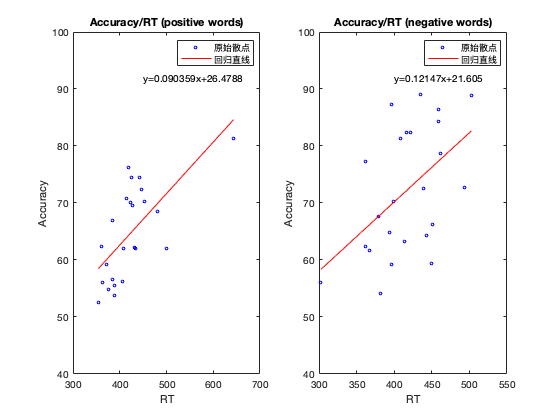

% calculation for necessary variables 
ACC1=acc_data(:,1); 
ACC2=acc_data(:,2); 
ps_mean=mean(rt_data(:,:,1),1)'; 
ng_mean=mean(rt_data(:,:,2),1)';

% for positive words condition
% linear regression : least square
xdata1 = [ones(size(ps_mean, 1), 1), ps_mean]; 
[b1, bint1, r1, rint1, s1] = regress(ACC1, xdata1); 
ACC1reg = xdata1*b1;
% for negative words condition
% linear regression : least square
xdata2 = [ones(size(ng_mean, 1), 1), ng_mean]; 
[b2, bint2, r2, rint2, s2] = regress(ACC2, xdata2); 
ACC2reg = xdata2*b2;

% figure
figure;
% subplot for positive words condition 
subplot(1,2,1)
plot(ps_mean, ACC1, 'bo', 'Markersize', 3);
hold on;
plot(ps_mean, ACC1reg, 'r-','linewidth', 1); 
xlim([300 700]);ylim([40 100]); 
xlabel('RT');ylabel('Accuracy');
legend('原始散点','回归直线');
text(450, 92, ['y=' num2str(b1(2)) 'x+' num2str(b1(1))]);
title('Accuracy/RT (positive words)');


% subplot for negative words condition
subplot(1,2,2)
plot(ng_mean, ACC2, 'bo', 'Markersize', 3); hold on;
plot(ng_mean, ACC2reg, 'r-','linewidth', 1); 
xlim([300 550]);ylim([40 100]); 
xlabel('RT');ylabel('Accuracy');
legend('原始散点','回归直线');
text(400, 92, ['y=' num2str(b2(2)) 'x+' num2str(b2(1))]);
title('Accuracy/RT (negative words)');